## AOMIC PIOP1 Replication Sample: Whole-Brain Coupling Plot Across Coupling Measures

Computation of coupling measure-specific brain-average coupling values for all six conditions, taking the mean across the eight condition-specific coupling values per coupling measure and creating the violin plot visualizing coupling measure-specific differences in brain-average SC-FC coupling. Run ANOVA to test for significant differences between brain-average measure-specific SC-FC coupling.

Before running this script: 

- run all scripts in AOMIC Data Prep 

**1. Compute brain-average coupling values **

1.1. Resting-state 

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_rest{i,1} = mean(final_r_all_AOMIC_PIOP1_rest_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_rest{i,2} = mean(final_r_all_AOMIC_PIOP1_rest_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_rest{i,3} = mean(final_r_all_AOMIC_PIOP1_rest_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_rest{i,4} = mean(final_r_all_AOMIC_PIOP1_rest_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_rest_table = cell2table(whole_brain_values_AOMIC_PIOP1_rest);
 whole_brain_values_AOMIC_PIOP1_rest_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_rest_table = 126×4 table
      Pl          G         Cos         SI   
    _______    _______    _______    ________

    0.15524    0.18762    0.19119     0.10006
    0.18329    0.19622    0.21093     0.15839
    0.16896    0.18045    0.18491      0.1415
     0.1816    0.19653    0.20223     0.16437
    0.17209    0.18853    0.19598     0.16306
    0.14889    0.16609    0.16575     0.12182
    0.18225    0.19217    0.19615     0.15667
    0.13544    0.15965    0.14996    0.092428
     0.1916    0.19919    0.21027      0.1751
    0.15506    0.15945    0.15978     0.11256
    0.18763    0.19177    0.20087     0.14009
    0.23858    0.22074    0.25011     0.23955
    0.16688    0.17532    0.17435     0.13677
    0.15612    0.17346     0.1731     0.11762
    0.14541    0.16984    0.16619     0.10298
    0.18344    0.18159   

1.2. Working memory

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_wm{i,1} = mean(final_r_all_AOMIC_PIOP1_wm_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_wm{i,2} = mean(final_r_all_AOMIC_PIOP1_wm_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_wm{i,3} = mean(final_r_all_AOMIC_PIOP1_wm_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_wm{i,4} = mean(final_r_all_AOMIC_PIOP1_wm_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_wm_table = cell2table(whole_brain_values_AOMIC_PIOP1_wm);
 whole_brain_values_AOMIC_PIOP1_wm_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_wm_table = 126×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.22647    0.26598    0.27468    0.17794
    0.22492    0.24844     0.2546    0.19878
    0.20101    0.22982    0.22257    0.16106
     0.2365    0.24162    0.24748     0.2212
    0.24396     0.2568     0.2578    0.24257
    0.21787    0.24632    0.25564    0.20369
    0.25847     0.2811    0.29852    0.24651
    0.20764    0.23825    0.23631    0.14667
    0.22145    0.24394    0.24791      0.216
    0.21739    0.23331     0.2356    0.13865
     0.2643    0.27869    0.29758    0.23759
    0.22595     0.2421    0.24681    0.19598
    0.23973    0.24595    0.24565    0.20594
    0.23471    0.25908    0.26559    0.17991
     0.2127    0.26028    0.26309    0.15811
    0.24757    0.24504    0.24413    0.19914

1.3. Emotion anticipation

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_emo_anti{i,1} = mean(final_r_all_AOMIC_PIOP1_emo_anti_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_emo_anti{i,2} = mean(final_r_all_AOMIC_PIOP1_emo_anti_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_emo_anti{i,3} = mean(final_r_all_AOMIC_PIOP1_emo_anti_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_emo_anti{i,4} = mean(final_r_all_AOMIC_PIOP1_emo_anti_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_emo_anti_table = cell2table(whole_brain_values_AOMIC_PIOP1_emo_anti);
 whole_brain_values_AOMIC_PIOP1_emo_anti_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_emo_anti_table = 126×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

     0.2354    0.27376     0.2785     0.1837
    0.23354    0.25716    0.26735    0.22646
    0.24193    0.25428    0.25999    0.21827
    0.25664    0.25054    0.25997    0.25009
    0.26153    0.28278    0.28579    0.27837
    0.21617    0.25751    0.26004    0.19922
    0.24166    0.26947    0.27914     0.2494
    0.20453     0.2279    0.22745    0.14394
    0.25345      0.274    0.29384    0.25543
    0.24725    0.25245     0.2599    0.17864
    0.28195    0.28969      0.303    0.25091
    0.24558    0.26414    0.27359    0.21073
     0.2548    0.26078    0.26423    0.22188
    0.29386    0.29756     0.3178    0.25718
    0.24124    0.27669    0.28566    0.18123
    0.26906    0.25528    0.26493    0

1.4. Emotion matching 

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_emo_match{i,1} = mean(final_r_all_AOMIC_PIOP1_emo_match_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_emo_match{i,2} = mean(final_r_all_AOMIC_PIOP1_emo_match_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_emo_match{i,3} = mean(final_r_all_AOMIC_PIOP1_emo_match_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_emo_match{i,4} = mean(final_r_all_AOMIC_PIOP1_emo_match_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_emo_match_table = cell2table(whole_brain_values_AOMIC_PIOP1_emo_match);
 whole_brain_values_AOMIC_PIOP1_emo_match_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_emo_match_table = 126×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.19544     0.2301    0.23142    0.13777
    0.18957    0.22022    0.22366     0.1616
    0.21882    0.22747     0.2311    0.19391
    0.22795    0.23716     0.2463    0.20913
    0.26798    0.27573    0.28791    0.29326
     0.1995     0.2331    0.23732    0.17985
    0.21166    0.24699    0.24892    0.19699
    0.19569    0.21451    0.21722    0.15261
    0.20385    0.23557    0.23947    0.17146
    0.22573     0.2323    0.23441    0.15548
    0.25481    0.26453    0.27954    0.21975
    0.18435    0.20992    0.21065    0.16889
    0.18961    0.21588    0.21467    0.15204
    0.19867    0.23008     0.2324    0.16438
    0.17897    0.22793    0.22204    0.12248
    0.21586    0.21556    0.21923    

1.5. Face perception

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_face{i,1} = mean(final_r_all_AOMIC_PIOP1_face_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_face{i,2} = mean(final_r_all_AOMIC_PIOP1_face_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_face{i,3} = mean(final_r_all_AOMIC_PIOP1_face_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_face{i,4} = mean(final_r_all_AOMIC_PIOP1_face_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_face_table = cell2table(whole_brain_values_AOMIC_PIOP1_face);
 whole_brain_values_AOMIC_PIOP1_face_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_face_table = 126×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.13852    0.17694    0.17629    0.10132
    0.18791    0.20549    0.21584    0.16935
    0.19124     0.2013    0.20296    0.15657
     0.1935    0.20015    0.20131    0.18466
    0.19355    0.21442    0.21838    0.16068
    0.17296    0.20709    0.21964    0.16523
    0.23297    0.23625    0.24691    0.23515
     0.1731    0.18252    0.18988    0.10707
    0.19701    0.21183    0.22346    0.19009
    0.15342     0.1643    0.16253    0.10352
    0.22092     0.2146    0.22186    0.19621
    0.19327    0.21199     0.2228    0.16197
    0.19437    0.19398    0.19765    0.17158
    0.23117     0.2452    0.26597    0.19024
    0.15459    0.17971    0.19153    0.11829
     0.1764    0.17849    0.18065    0.164

1.6. Gender stroop

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_gender{i,1} = mean(final_r_all_AOMIC_PIOP1_gender_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_gender{i,2} = mean(final_r_all_AOMIC_PIOP1_gender_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_gender{i,3} = mean(final_r_all_AOMIC_PIOP1_gender_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_gender{i,4} = mean(final_r_all_AOMIC_PIOP1_gender_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_gender_table = cell2table(whole_brain_values_AOMIC_PIOP1_gender);
 whole_brain_values_AOMIC_PIOP1_gender_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_gender_table = 126×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

     0.2327    0.26595     0.2692    0.18498
    0.25731    0.27543    0.29302    0.25123
    0.25347    0.27252    0.27652    0.21499
     0.2447    0.24704    0.25959    0.22753
    0.30615    0.31327    0.32593    0.29537
    0.20969     0.2555    0.26111    0.18595
    0.25598    0.28781    0.29436    0.22863
    0.24889    0.26001    0.26239    0.17545
    0.26605    0.27937    0.29744    0.28012
    0.26393    0.26322     0.2723    0.20076
    0.27759    0.28958    0.30303    0.24439
    0.27566    0.27505    0.29615    0.27342
    0.26184    0.25844    0.26133    0.24015
    0.27009    0.28399    0.29943    0.24158
    0.22989    0.25765    0.26481    0.17366
    0.27152    0.25863    0.26965    0.2

**2. Average the coupling measure-specific values across all conditions**

2.1. Take average across all PL values 

PL_values_from_all_conditions = [whole_brain_values_AOMIC_PIOP1_rest_table.Pl whole_brain_values_AOMIC_PIOP1_wm_table.Pl whole_brain_values_AOMIC_PIOP1_emo_anti_table.Pl whole_brain_values_AOMIC_PIOP1_emo_match_table.Pl whole_brain_values_AOMIC_PIOP1_face_table.Pl whole_brain_values_AOMIC_PIOP1_gender_table.Pl]
PL_all = mean(PL_values_from_all_conditions,2)

2.2. Take average across all G values 

G_values_from_all_conditions = [whole_brain_values_AOMIC_PIOP1_rest_table.G whole_brain_values_AOMIC_PIOP1_wm_table.G whole_brain_values_AOMIC_PIOP1_emo_anti_table.G whole_brain_values_AOMIC_PIOP1_emo_match_table.G whole_brain_values_AOMIC_PIOP1_face_table.G whole_brain_values_AOMIC_PIOP1_gender_table.G]
G_all = mean(G_values_from_all_conditions,2)

2.3. Take average across all CoS values 

CoS_values_from_all_conditions = [whole_brain_values_AOMIC_PIOP1_rest_table.Cos whole_brain_values_AOMIC_PIOP1_wm_table.Cos whole_brain_values_AOMIC_PIOP1_emo_anti_table.Cos whole_brain_values_AOMIC_PIOP1_emo_match_table.Cos whole_brain_values_AOMIC_PIOP1_face_table.Cos whole_brain_values_AOMIC_PIOP1_gender_table.Cos]
CoS_all = mean(CoS_values_from_all_conditions,2)

2.4. Take average across all SI values 

SI_values_from_all_conditions = [whole_brain_values_AOMIC_PIOP1_rest_table.SI whole_brain_values_AOMIC_PIOP1_wm_table.SI whole_brain_values_AOMIC_PIOP1_emo_anti_table.SI whole_brain_values_AOMIC_PIOP1_emo_match_table.SI whole_brain_values_AOMIC_PIOP1_face_table.SI whole_brain_values_AOMIC_PIOP1_gender_table.SI]
SI_all = mean(SI_values_from_all_conditions,2)

**3. Create the violin plot**

3.1. Put all values into one table 

Mean_values_coupling_measures = [PL_all G_all CoS_all SI_all]
% Mean_values_coupling_measures_cell = num2cell(Mean_values_coupling_measures)
% Mean_values_coupling_measures_table = cell2table(Mean_values_coupling_measures_cell)
% Mean_values_coupling_measures_table.Properties.VariableNames = {'PL', 'G', 'CoS', 'SI'}

3.2. Create violin plots

 violinplot(Mean_values_coupling_measures)
 ylabel('Brain-average Coupling (r)')
 xlabel('Coupling Measure')
 set(gca,'FontSize',15)
 ylim([0.05 0.4])

**4. Run ANOVAs **

Mean_values_coupling_measures
groupnames = {'PL', 'G', 'CoS', 'SI'}

groupnames = 1×4 cell array
    {'PL'}    {'G'}    {'CoS'}    {'SI'}


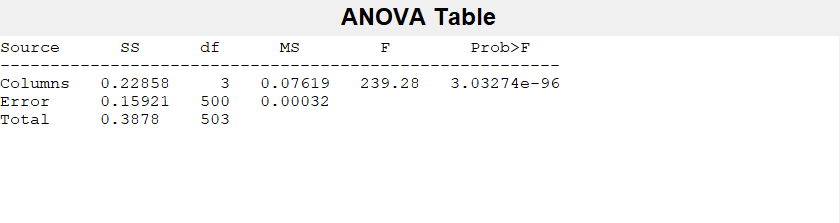

p = 3.0327e-96

tbl = 4×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[0.2286]}    {[  3]}    {[    0.0762]}    {[239.2838]}    {[3.0327e-96]}
    {'Error'  }    {[0.1592]}    {[500]}    {[3.1843e-04]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[0.3878]}    {[503]}    {0×0 double  }    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: [4×1 char]
         n: [126 126 126 126]
    source: 'anova1'
     means: [0.2125 0.2308 0.2362 0.1817]
        df: 500
         s: 0.0178


[p,tbl,stats] = anova1(Mean_values_coupling_measures)

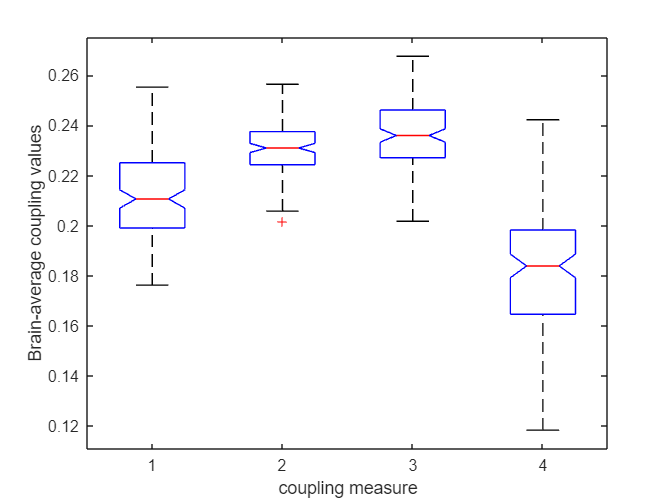

xlabel('coupling measure')
ylabel('Brain-average coupling values')

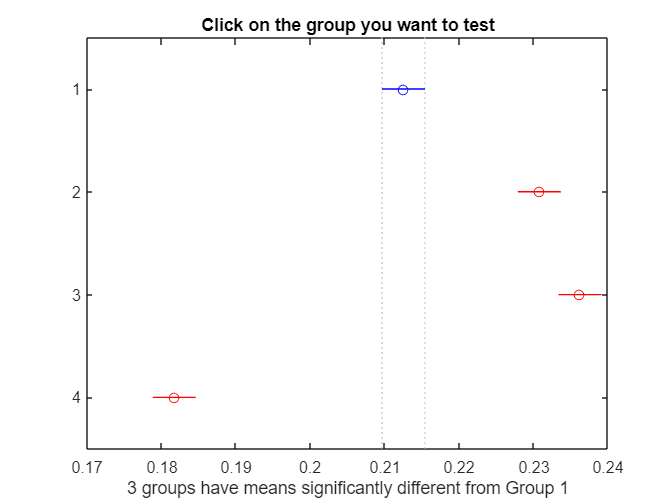

gnames = 4×1 char array
    '1'
    '2'
    '3'
    '4'


[c,~,~,gnames] = multcompare(stats)

table = array2table(c,"VariableNames",["Group A", "Group B", "Lower Limit", "A-B", "Upper Limit", "P-value"])

table = 6×6 table
    Group A    Group B    Lower Limit       A-B        Upper Limit     P-value  
    _______    _______    ___________    __________    ___________    __________

       1          2        -0.024043      -0.018267     -0.012491     1.5648e-15
       1          3        -0.029508      -0.023733     -0.017957              0
       1          4         0.025024       0.030799      0.036575              0
       2          3        -0.011241     -0.0054654    0.00031027       0.071347
       2          4         0.043291       0.049066      0.054842              0
       3          4         0.048756       0.054532      0.060308              0
